clc;clear all;close all;

fprintf('DB_DATA\r\n');

DB_DATA


cla_data = open_and_importdata('G:\論文\1080919\FULL\2F');
fprintf('PCA_DATA\r\n');

PCA_DATA


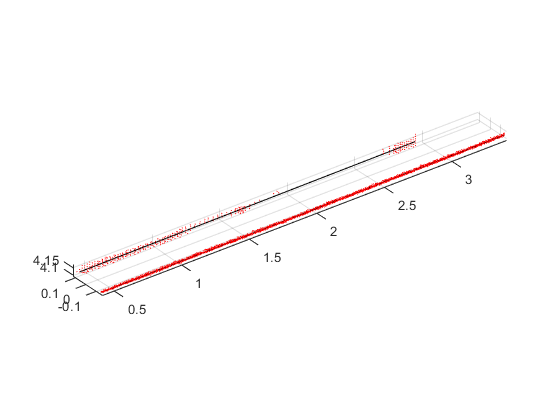

pca_data = open_and_importdata('G:\論文\1080919\FULL\2F');

%B1=5,B2=17.5,B4=42.5,B6=67.5,M=130,T6=192.5,T4=217.5,T2=242.5,T1=255

group_num = 1;

figure(1)
scatter3(pca_data(:,1),pca_data(:,2),pca_data(:,3),1,'r','filled');hold on
axis equal
cla_data_X = cla_data(find(cla_data(:,4)==1),:);


start=zeros(4,3);
start(:,1)=0.28;

B1=zeros(4,3);
B1(:,1)=1.085;

B2=zeros(4,3);
B2(:,1)=1.89;

B3=zeros(4,3);
B3(:,1)=2.695;

Bot=zeros(4,3);
Bot(:,1)=3.5;


group_num = max(cla_data_X(:,5));
group_mean=zeros(group_num,4);
for i=1:group_num
    samegroup = find(cla_data_X(:,5)==i);
    for j=1:size(samegroup)
        cla_data_X(samegroup(j),6)=group_mean(i,1);
    end
end

new_group=[];
for i=1:max(cla_data_X(:,5))
    new_group_num = find(cla_data_X(:,5)==i);
    if size(new_group_num)~=0
        new_group(i,:) = cla_data_X(new_group_num(1,1),:);
    end
end
new_group(all(new_group==0,2),:)=[];
for i=1:size(new_group)
    new_group(i,6)=i;
end
new_group_data=[];
for i=1:size(new_group)
    new_group_data = find(cla_data_X(:,5)==new_group(i,5));
    cla_data_X(new_group_data(:,1),6)=new_group(i,6);
end
if cla_data(:,4)==1
    for i=1:1:max(cla_data_X(:,6))
        group = [];
        group = find(cla_data_X(:,6)==i);
        
        x = cla_data_X(group,1);
        y = cla_data_X(group,2);
        z = cla_data_X(group,3);
        
        % 分別擬合兩個二維的曲線，然後統一到一起
        p_xy = polyfit(x,y,1);
        y_out = polyval(p_xy,x);
        
        start(i,2)=polyval(p_xy,start(i,1));
        B1(i,2)=polyval(p_xy,B1(i,1));
        B2(i,2)=polyval(p_xy,B2(i,1));
        B3(i,2)=polyval(p_xy,B3(i,1));
        Bot(i,2)=polyval(p_xy,Bot(i,1));
        
        p_xz = polyfit(x,z,1);
        z_out=polyval(p_xz,x);
        
        start(i,3)=polyval(p_xz,start(i,1));
        B1(i,3)=polyval(p_xz,B1(i,1));
        B2(i,3)=polyval(p_xz,B2(i,1));
        B3(i,3)=polyval(p_xz,B3(i,1));
        Bot(i,3)=polyval(p_xz,Bot(i,1));
        
        % 得出曲線函數 x_out = f(z_out)   z_out = f(y)
        p_xz_out = polyfit(z_out,y_out,1);
        y_out_f = polyval(p_xz_out,z_out);
        
        start(i,2)=polyval(p_xz_out,start(i,3));
        B1(i,2)=polyval(p_xz_out,B1(i,3));
        B2(i,2)=polyval(p_xz_out,B2(i,3));
        B3(i,2)=polyval(p_xz_out,B3(i,3));
        Bot(i,2)=polyval(p_xz_out,Bot(i,3));
        
        
        group_num = group_num +1;
        figure(1)
        plot3(x,y_out_f,z_out,'k'); hold on; %畫曲線，每次迴圈根換資料和顏色
    end
end

DATA = [start;B1;B2;B3;Bot];
% xlswrite('F:\論文\1080919\FULL\20210415\20210501\B11\B11_0919_DATA_20210501.xlsx',DATA);